clc; clear; close all;

% Define continuous-time transfer function
s = tf('s');
H_fit = (0.01197*s^4 - 40.03*s^2 + 461.3) / ...
        (s^4 - 482.7*s^2 + 65.13);

% Sampling time (choose based on your data, e.g., 10 Hz → Ts = 0.1 s)
Ts = 0.1;

% Discretize using bilinear (Tustin) method
H_fit_d = c2d(H_fit, Ts, 'tustin');

% Display results
H_fit

H_fit =
 
  0.01197 s^4 - 40.03 s^2 + 461.3
  -------------------------------
      s^4 - 482.7 s^2 + 65.13
 
Continuous-time transfer function.
Model Properties


H_fit_d

H_fit_d =
 
  0.413 z^4 + 0.1762 z^3 - 1.402 z^2 + 0.1762 z + 0.413
  -----------------------------------------------------
        z^4 + 19.38 z^3 - 40.79 z^2 + 19.38 z + 1
 
Sample time: 0.1 seconds
Discrete-time transfer function.
Model Properties


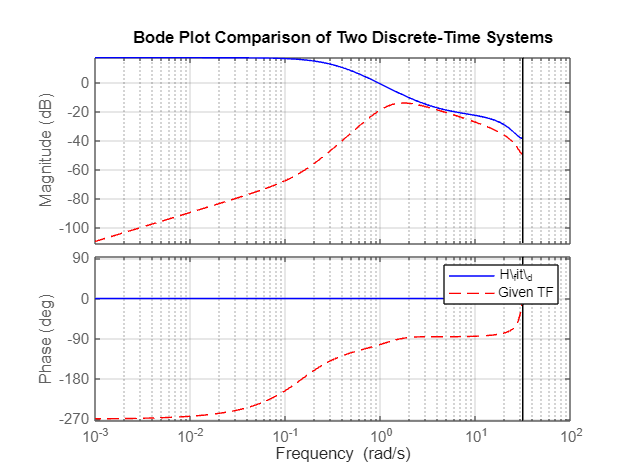




%% First discrete-time TF: H_fit_d
num1 = [0.413 0.1762 -1.402 0.1762 0.413];
den1 = [1 19.38 -40.79 19.38 1];
Ts = 0.1; % sample time in seconds
H1 = tf(num1, den1, Ts);

%% Second discrete-time TF: given one
num2 = [0.02679 -0.05951 0.01895 0.03348 -0.01971];
den2 = [1 -3.952 5.857 -3.857 0.9523];
H2 = tf(num2, den2, Ts);

%% Bode plot comparison
figure;
bode(H1, 'b', H2, 'r--');
grid on;
legend('H\_fit\_d', 'Given TF');
title('Bode Plot Comparison of Two Discrete-Time Systems');

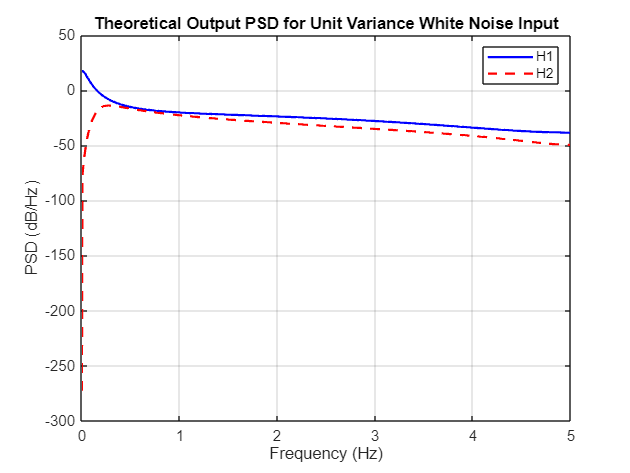




%% Define transfer functions
num1 = [0.413 0.1762 -1.402 0.1762 0.413];
den1 = [1 19.38 -40.79 19.38 1];

num2 = [0.02679 -0.05951 0.01895 0.03348 -0.01971];
den2 = [1 -3.952 5.857 -3.857 0.9523];

Ts = 0.1; % sample time

%% Frequency vector for plotting
nfft = 1024;
[H1_w, w] = freqz(num1, den1, nfft, 1/Ts);
[H2_w, ~]  = freqz(num2, den2, nfft, 1/Ts);

%% For white noise input with unit variance:
PSD1 = abs(H1_w).^2; % output PSD
PSD2 = abs(H2_w).^2;

%% Plot in dB/Hz
figure;
plot(w, 10*log10(PSD1), 'b', 'LineWidth', 1.5); hold on;
plot(w, 10*log10(PSD2), 'r--', 'LineWidth', 1.5);
grid on;
xlabel('Frequency (Hz)');
ylabel('PSD (dB/Hz)');
legend('H1', 'H2');
title('Theoretical Output PSD for Unit Variance White Noise Input');